# **The laboratory work # 9**

Space Data Processing class

# **Process reconstruction free from any constraints and assumptions**

- Axel Garcia

- Shipitko Oleg.

 Skoltech, Spring 2016

clc; clear all;
addpath('Functions');

% Loading the data
importdata('Sunspot.mat');

Error using importdata (line 136)
Unable to open file.


sunSpot = MSN(:,4);

smoothedSunSpot = sunSpot;

smoothedSunSpot(1:6) = mean(sunSpot(1:6));
for i = 7 : length(sunSpot) - 6
    smoothedSunSpot(i) = (sunSpot(i - 6) + sunSpot(i + 6))/24 + sum(sunSpot(i-5 : i+5))/12;
end
smoothedSunSpot(end - 5 : end) = mean(sunSpot(end - 5 : end));

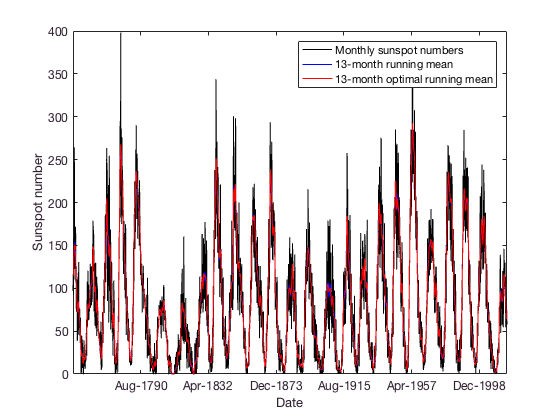

beta = 0.01;

d2 = ones(11, 1);
d1 = [-2; -4*ones(10, 1); -2];
d0 = [1+beta; 5+beta; (6+beta)*ones(9,1); 5+beta; 1+beta];

A = diag(d0) + diag(d1, -1) + diag(d1, 1) + diag(d2, -2) + diag(d2, 2);
A_inv = inv(A);

optimalSmoothedSunSpot = zeros(length(sunSpot),1);

optimalSmoothedSunSpot(1:6) = mean(sunSpot(1:6));
for i = 7:length(sunSpot)-6
    optimalSmoothedSunSpot(i) = beta * A_inv(7,:) * sunSpot(i-6:i+6);
end    
optimalSmoothedSunSpot(end - 5 : end) = mean(sunSpot(end - 5 : end));

plot(sunSpot, 'black')
hold on
plot(smoothedSunSpot, 'blue')
plot(optimalSmoothedSunSpot, 'red')
hold off
xlim( [1, length(sunSpot)])
lg = legend('Monthly sunspot numbers', '13-month running mean', '13-month optimal running mean'); 
xt = get(gca, 'xtick'); 
dateVector = MSN(:, 3); 
set(gca,  'xticklabel', datestr(dateVector(xt), 'mmm-yyyy'), 'FontSize', 12) 
ylabel('Sunspot number') 
xlabel('Date')

I_v_smoothed = calcVariabilityIndicator(smoothedSunSpot);
I_v_optimalSmoothed = calcVariabilityIndicator(optimalSmoothedSunSpot);
I_v_smoothed/I_v_optimalSmoothed

ans = 3.0865

I_d_smoothed = calcDeviationIndicator(smoothedSunSpot, sunSpot);
I_d_optimalSmoothed = calcDeviationIndicator(optimalSmoothedSunSpot, sunSpot);
I_d_smoothed/I_d_optimalSmoothed

ans = 1.1649